# **Coherence and interference**

Ian Cooper

School of Physics, University of Sydney

DOING PHYSICS WITH MATLAB: www.physics.usyd.edu.au/teach_res/mp/mphome.htm

Documentation: www.physics.usyd.edu.au/teach_res/mp/doc/op???.htm

Mscripts: www.physics.usyd.edu.au/teach_res/mp/mscripts

Matlab 2018b  1812178     op_LE_300.mlx

When the phase difference between two waves is constant, they are **mutually coherent **waves. In practice, this conditions is not usually met and we then refer to the waves as being **partially coherent**. 


clear
close all
clc



% INPUT SECTION ================================================================

% Time domain number of grid points (must be an odd integer)
Nt = 1255;  

% Relative phase difference  phi  [rad]
  % flagP = 1   mutual coherence: constant phase difference
  % flagP = 2   partial coherence: random phase difference
  % flagP = 3   partial coherence: continual drift in the phase difference
flagP = 1;

  phi = (0) .* ones(Nt,1);
  if flagP == 2; phi = 2*pi*rand(Nt,1); end
  if flagP == 3
     for cc = 1 : Nt
       phi(cc) = (cc-1) * 2*pi/(Nt-1);
     end
  end
% Electric fields E1 and E2: amplitudes [a.u.] / wavelengths [nm] 
E0 = [1, 1];

% wavelengths 1 and 2: visible part of EM spectrum  [380 nm to 750 nm] 

wL = [720, 720];

% Sources: S1(0, y1) and S2(0, y2)    [m]
y1 = 1e-6; y2 = -y1;

% Detector positions P(x,y) [m]
Ny = 5211;
yMax = 1;
x = 1;
y = linspace(-yMax,yMax,Ny);



% CALCULATION SECTION  ================================================

% Speed of light
  c = 3e8;
% Propagation constant  k  [rad/m]
  k = 2*pi./(wL*1e-9);
% Frequency  f  [Hz]
  f = c./wL;
% Angular frequency  w  [rad/s]  
  w = 2*pi.*f;
  dw = w(2) - w(1);
% Period  T  [s] 
  T = 1./f;
  Tmax = max(T);
%  Time domain
  tMin = 0; tMax = 5*max(T);
  t = linspace(tMin,tMax,Nt);
  
%  distance r  [m]
  r1 = sqrt(x.^2 + (y1 - y).^2);
  r2 = sqrt(x.^2 + (y2 - y).^2);
  
% amplitudes [a.u.]
  A1 = (E0(1) ./ r1) .* exp(1i*k(1)*r1); 
  A2 = (E0(2) ./ r2) .* exp(1i*k(2)*r2); 
  A1 = A1'; A2 = A2';
% Electric field  [a.u.]
  E1 = zeros(Ny,Nt);
  E2 = zeros(Ny,Nt);
    for cc = 1:Nt
       E1(:,cc) = A1 .* exp(-1i*w(1)*t(cc));
       E2(:,cc) = A2 .* exp(-1i*w(1)*t(cc)) .* exp(-1i*dw*t(cc)) .* exp(1i*phi(cc));
    end
  E = E1 + E2; 
  
% Irradiance  [a.u.]
  IRR = zeros(Ny,1); IRR1 = zeros(Ny,1); IRR2 = zeros(Ny,1);
    for cc = 1:Ny 
      IRR(cc) = (1/Tmax).* simpson1d(E(cc,:).*conj(E(cc,:)),0,Tmax);
      IRR1(cc) = (1/Tmax).* simpson1d(E1(cc,:).*conj(E1(cc,:)),0,Tmax);
      IRR2(cc) = (1/Tmax).* simpson1d(E2(cc,:).*conj(E2(cc,:)),0,Tmax);
      
    end

% Mutual coherence function
  gamma = zeros(Ny,1); 
    for cc = 1:Ny 
      gamma(cc) = (1/Tmax).* simpson1d(E1(cc,:).*conj(E2(cc,:)),0,Tmax);
    end


% Visibilty
   V = (max(IRR) - min(IRR)) / (max(IRR) + min(IRR))

V = 1.0000

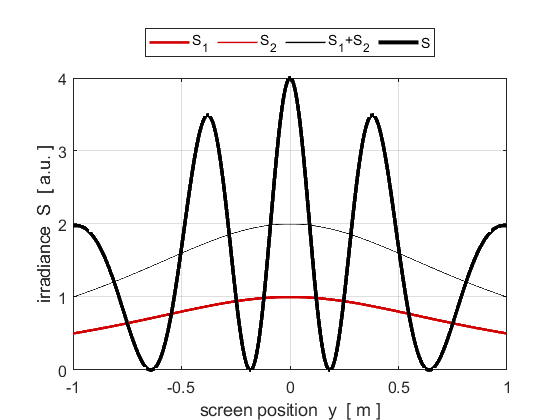

    
  % GRAPHICS SECTION  =================================================
  
  figure(1)
  % color of plot to match "true" wavelength color  
  
    col = ColorCode(wL(1)*1e-9);
    xP = y; yP = IRR1; 
    plot(xP,yP,'color',col,'linewidth',2)
  
    hold on
  
    col = ColorCode(wL(2)*1e-9);
    xP = y; yP = IRR2; 
    plot(xP,yP,'color',col,'linewidth',1)
    
    xP = y; yP = IRR1+IRR2; 
    plot(xP,yP,'k','linewidth',1)
    
    xP = y; yP = IRR; 
    plot(xP,yP,'k','linewidth',3)
     
    ylim([0 4])
    legend('S_1','S_2','S_1+S_2','S','location','northoutside','orientation','horizontal')
  
    grid on
    ylabel('irradiance  S  [ a.u. ]')
    xlabel('screen position  y  [ m ]')
    set(gca,'fontsize',12)

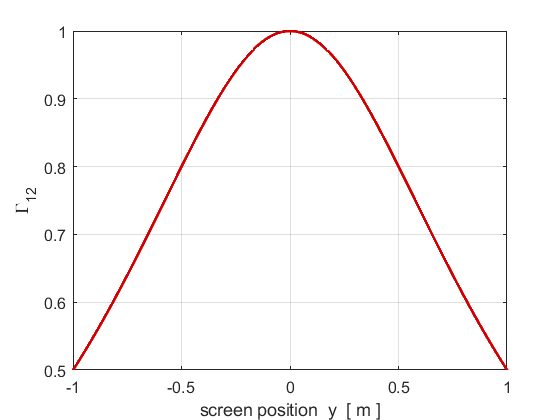

  
  figure(2)
  % color of plot to match "true" wavelength color  
  if wL(1) == wL(2)
      col = ColorCode(wL(1)*1e-9);
  else
      col = [0 0 0];
  end
  
  xP = y; yP = abs(gamma); 
  plot(xP,yP,'color',col,'linewidth',2)
  %ylim([0 4])
  
  grid on
  ylabel('\Gamma_{12}')
  xlabel('screen position  y  [ m ]')
  set(gca,'fontsize',12)